# modeling growth of k. rhaeticus, consumption of glucose, and synthesis of bacterial cellulose: part 2 of 2

taking the results from part 1 and applying them to data with inital conditions

% created 03/19/2026 17:01 
% last edited 05/05/2026 14:28
clear; close all;

% import the workspace_6well.mat file
tData = [dayno;dayno;dayno]; % units: days

XData = [ODA;ODB;ODC]; % units: OD600
SData = [glucA;glucB;glucC]; % units: g/L

vol = 0.01; % units: L (10 mL per each of 6 tubes)
PDatag = [pellmA;pellmB;pellmC]; % units: g
PData = PDatag/vol; % units: g/L 

[tData,idx] = sort(tData);
XData = XData(idx);
SData = SData(idx);
PData = PData(idx);

% have to get rid of all the 0s at the start of PData so that the graph
% doesn't turn out totally flat
PData(1:6,1) = 1e-4;

RGB = orderedcolors("gem");
gem_blue = RGB(1,:);
gem_red = RGB(2,:);
gem_orange = RGB(3,:);
gem_purple = RGB(4,:);
gem_green = RGB(5,:);
gem_teal = RGB(6,:);
gem_pink = RGB(7,:);

% plot the ODEs over 15 days
tspan = [0 15];

% dense time vector for smooth plotting
tPlot = linspace(tspan(1), tspan(2), 500);

% initial conditions for ABC in 6-well experiment
X0 = 0.051; % units: OD600
S0 = 10; % units: g/L
P0 = 1e-4; % units: g/L (actually = 0 but glitchy with that)

% % initial conditions for DEF in 6-well experiment
% X0 = 0.044; % units: OD600
% S0 = 14; % units: g/L
% P0 = 1e-4; % units: g/L (actually = 0 but glitchy with that)

y0 = [X0; S0; P0];

params.S0     = S0;   % needed inside pH model

params.mu_max = 0.571873;
params.Ks = 6.93295;
params.alpha = 0.602013;
params.beta = 9.47756;
params.ms = 0.200211;
params.Yxs = 0.00972188;
params.Yps = 0.434737;
params.gamma = 11.9936;
params.k_pH = 17.339;
params.eta = 0.1443;
params.pH0    = 5.9;
params.pHcrit = 5.0;

%% solve ODE
opts = odeset('NonNegative',1:3);  % keeps X,S,P nonnegative if possible
[tSol, ySol] = ode45(@(t,y) rhs_t(t, y, params), tPlot, y0, opts);

% extract model solutions
XModel = ySol(:,1);
SModel = ySol(:,2);
PModel = ySol(:,3);

%% interpolate model at experimental data times
XModel_data = interp1(tSol, XModel, tData, 'pchip');
SModel_data = interp1(tSol, SModel, tData, 'pchip');
PModel_data = interp1(tSol, PModel, tData, 'pchip');

%% compute NRMSE
% where NRMSE = RMSE / (max(data)-min(data))
NRMSE_X = computeNRMSE(XData, XModel_data);
NRMSE_S = computeNRMSE(SData, SModel_data);
NRMSE_P = computeNRMSE(PData, PModel_data);

fprintf('NRMSE for X(t): %.4f\n', NRMSE_X);

NRMSE for X(t): 0.1981


fprintf('NRMSE for S(t): %.4f\n', NRMSE_S);

NRMSE for S(t): 0.1271


fprintf('NRMSE for P(t): %.4f\n', NRMSE_P);

NRMSE for P(t): 0.1348


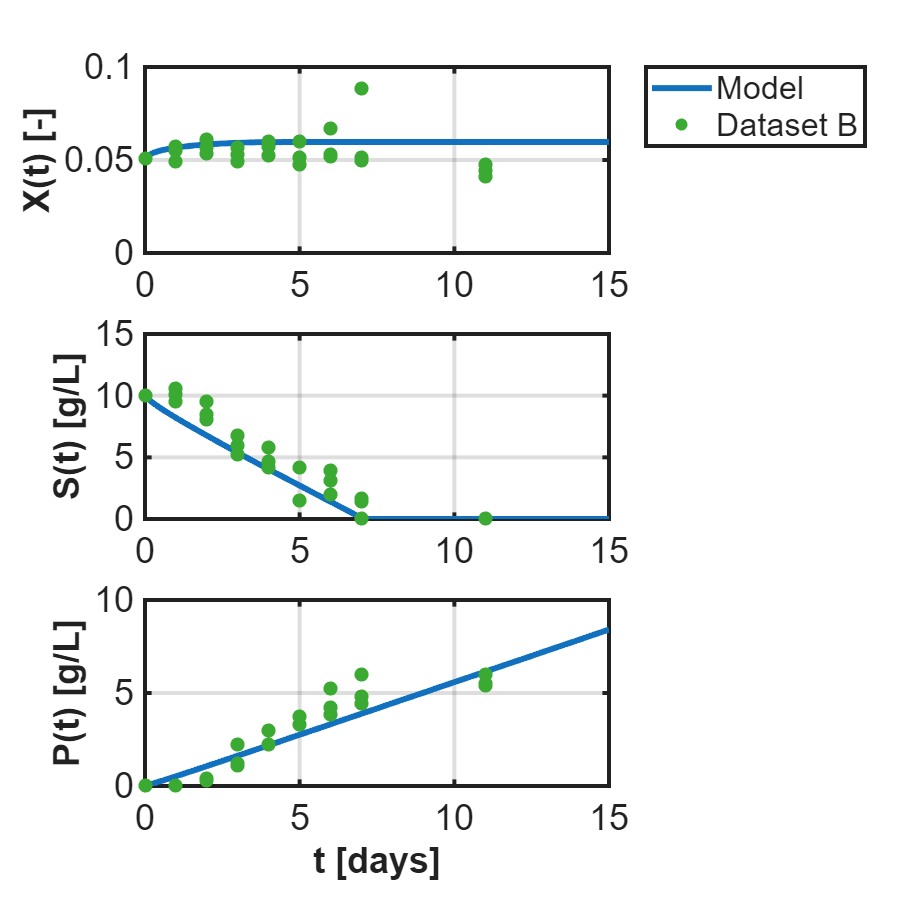


%% PLOT
figure;
tiledlayout(3,1,"TileSpacing","compact");

% X
nexttile; hold on; grid on;
plot(tSol, XModel, 'LineWidth', 3);
scatter(tData, XData, 50, gem_green, 'filled');
ylabel('X(t) [-]');
xlim([0 15]);
ylim([0 0.1]);
% title(sprintf('Biomass X(t)   |   NRMSE = %.4f', NRMSE_X));
legend('Model', 'Dataset B', 'Location', 'northeastoutside');

% S
nexttile; hold on; grid on;
plot(tSol, SModel, 'LineWidth', 3);
scatter(tData, SData, 50, gem_green, 'filled');
ylabel('S(t) [g/L]');
xlim([0 15]);
ylim([0 15]);
% title(sprintf('Substrate S(t)   |   NRMSE = %.4f', NRMSE_S));
% legend('Model', 'Data', 'Location', 'best');

% P
nexttile; hold on; grid on;
plot(tSol, PModel, 'LineWidth', 3);
scatter(tData, PData, 50, gem_green, 'filled');
ylabel('P(t) [g/L]');
xlabel('t [days]');
xlim([0 15]);
ylim([0 10]);
% title(sprintf('Product P(t)   |   NRMSE = %.4f', NRMSE_P));
% legend('Model', 'Data', 'Location', 'best');

improvePlot()

function dydt = rhs_t(~, y, params)
    X = y(1);
    S = y(2);
    P = y(3);

    % initial conditions for ABC in 6-well experiment
    % X0 = 0.051; % units: OD600
    % S0 = 10; % units: g/L
    % P0 = 1e-4; % units: g/L (actually = 0 but glitchy with that)

    % initial conditions for DEF in 6-well experiment
    X0 = 0.044; % units: OD600
    S0 = 14; % units: g/L
    P0 = 1e-4; % units: g/L (actually = 0 but glitchy with that)
    
    % initial conditions
    y0 = [X0; S0; P0];

    % parameters from estimation using samples DEF from 6-well experiment
        % unpack parameters
    mu_max = params.mu_max;
    Ks     = params.Ks;
    alpha  = params.alpha;
    beta   = params.beta;
    ms     = params.ms;
    Yxs    = params.Yxs;
    Yps    = params.Yps;
    gamma  = params.gamma;
    k_pH   = params.k_pH;
    eta    = params.eta;
    pH0    = params.pH0;
    pHcrit = params.pHcrit;
    S0     = params.S0;
    
    % measured
    pH0 = 5.8;
    
    % based on my observations
    pHcrit = 5.0;

    pH = pH0 - eta * (S0 - S);
    f_pH = 1 / (1 + exp(k_pH * (pHcrit - pH)));
    f_P = 1 / (1 + gamma * P);
    
    % monod equations
    mu = mu_max * (S / (Ks + S)) * f_P * f_pH;
    
    k11 = 1 / Yxs + alpha / Yps;
    k12 = beta / Yps + ms;

    dX_dt = mu*X;
    dS_dt = -(k11*mu + k12)*X;
    dP_dt = alpha*mu*X + beta*X;

    dydt = [dX_dt; dS_dt; dP_dt];
end

function nrmse = computeNRMSE(yData, yModel)
    rmse = sqrt(mean((yData - yModel).^2, 'omitnan'));
    dataRange = max(yData) - min(yData);

    if dataRange == 0
        nrmse = NaN;
    else
        nrmse = rmse / dataRange;
    end
end